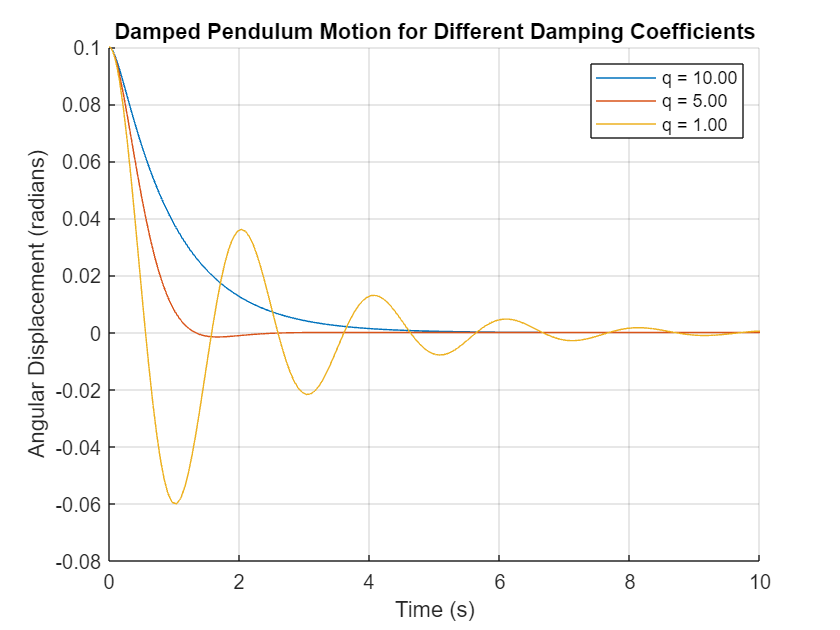


    % Constants
    g = 9.8;     % acceleration due to gravity (m/s^2)
    l = 1.0;     % length of the pendulum (m)
    theta0 = 0.1; % initial angle (radians)

    % Time span
    tspan = [0 10]; % time interval from 0 to 20 seconds

    % Damping coefficients for underdamped, critically damped, and overdamped
    q_under = 10;
    q_critical = 5;
    q_over = 1;
    q_values = [q_under, q_critical, q_over];

    % Simulate and plot the results for each damping coefficient
    figure;
    hold on;

    for q = q_values
        % Define the ODE
        odefun = @(t, y) [y(2); -g/l * sin(y(1)) - q * y(2)];

        % Initial conditions [theta0; omega0]
        y0 = [theta0; 0];

        % Solve ODE
        [t, y] = ode45(odefun, tspan, y0);

        % Plot the results
        plot(t, y(:, 1), 'DisplayName', sprintf('q = %.2f', q));
    end

    % Customize the plot
    title('Damped Pendulum Motion for Different Damping Coefficients');
    xlabel('Time (s)');
    ylabel('Angular Displacement (radians)');
    legend;
    grid on;
    hold off;

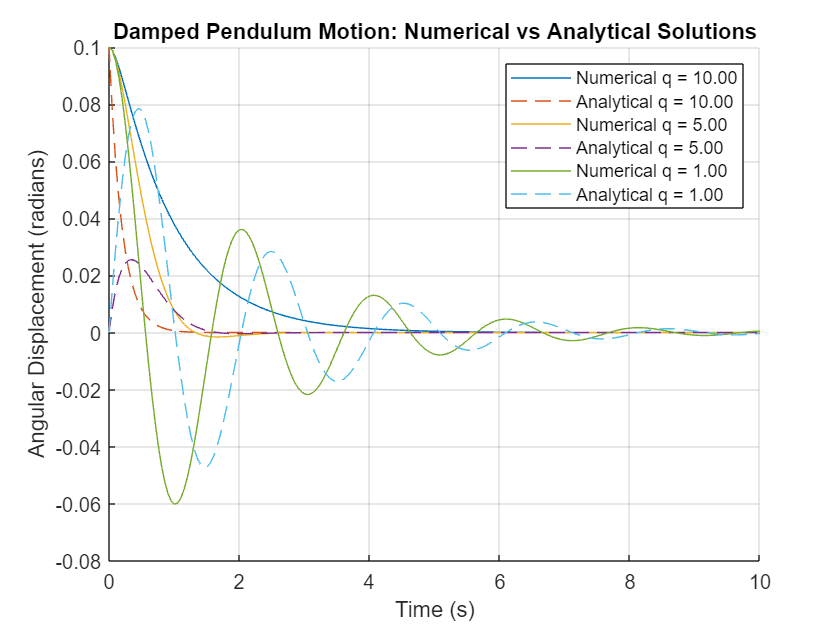


    % Constants
    g = 9.8;      % acceleration due to gravity (m/s^2)
    l = 1.0;      % length of the pendulum (m)
    theta0 = 0.1; % initial angle (radians)
    Omega = sqrt(g/l); % undamped natural frequency

    % Time span
    t = linspace(0, 10, 200); % time vector

    % Damping coefficients for underdamped, critically damped, and overdamped
    q_under = 10;
    q_critical = 5;
    q_over = 1;
    q_values = [q_under, q_critical, q_over];

    % Plot the results for each damping coefficient
    figure;
    hold on;

    for q = q_values
        % Numerical solution
        odefun = @(t, y) [y(2); -g/l * sin(y(1)) - q * y(2)];
        y0 = [theta0; 0];
        [t_num, y_num] = ode45(odefun, t, y0);

        % Analytical solution
        if q < 2*Omega
            omega_d = sqrt(Omega^2 - (q/2)^2); % damped natural frequency
            theta_analytical = theta0 * exp(-q/:2 .* t) .* sin(omega_d * t);
        else
            theta_analytical = theta0 * exp(-q/2 .* t);
        end

        % Plot numerical solution
        plot(t_num, y_num(:, 1), 'DisplayName', sprintf('Numerical q = %.2f', q));
        
        % Plot analytical solution
        plot(t, theta_analytical, '--', 'DisplayName', sprintf('Analytical q = %.2f', q));
    end

    % Customize the plot
    title('Damped Pendulum Motion: Numerical vs Analytical Solutions');
    xlabel('Time (s)');
    ylabel('Angular Displacement (radians)');
    legend;
    grid on;
    hold off;